# Cable-Cable Interference-Free Workspace Analysis 

clear;

### Load the robot 

Load the robot in the manner shown in `T1_load_robot.mlx`.

% model_config = ModelConfig('Example spatial');
model_config = ModelConfig('BMArm');
cdpr_model = model_config.getModel('multi_link', [], ModelModeType.COMPILED); % Compiled mode needs to fix the plotting TODO

[INFO] Creating symbolic model
[INFO] - Symbolic simplifying of R_0k for body 1
[INFO] - Symbolic simplifying of r_OP for body 1
[INFO] - Symbolic simplifying of R_0k for body 2
[INFO] - Symbolic simplifying of r_OP for body 2
[INFO] Symbolic computing of S and S_dot
[INFO] Symbolic computing/simplifying of P
[INFO] - Symbolic computing of P_ak, k: 1, a: 1
[INFO] - Symbolic simplifying of R_ka, k: 1, a: 1
[INFO] - Symbolic simplifying of P_ak, k: 1, a: 1
[INFO] - Symbolic computing of P_ak, k: 2, a: 1
[INFO] - Symbolic simplifying of R_ka, k: 2, a: 1
[INFO] - Symbolic simplifying of P_ak, k: 2, a: 1
[INFO] - Symbolic computing of P_ak, k: 2, a: 2
[INFO] - Symbolic simplifying of R_ka, k: 2, a: 2
[INFO] - Symbolic simplifying of P_ak, k: 2, a: 2
[INFO] Symbolic computing of W
[INFO] Symbolic computing/simplifying of C_a
[INFO] Symbolic computing M_b, C_b, G_b terms
[INFO] Symbolic computing of M, C, G terms
[INFO] Symbolic computing/simplifying of cable kinematics
[INFO] - Symbolic comp

%model_options = ModelOptions(false);
% cdpr_model = model_config.getModel('cross_8_cables', [], ModelModeType.COMPILED); % Compiled mode needs to fix the plotting TODO
% MotionSimulatorBase.PlotFrame(cdpr_model_cogiro, model_config_cogiro.displayRange, model_config_cogiro.viewAngle); % Plot robot

### Setup the grid

A uniform (equal spacing) grid will be setup representing the set of rays which the workspace analysis will be run.

% q_min            = [0; 0; 0; 0.4; 0.2; 0.8];
% q_max            = [1; 1; 1; 0.4; 0.2; 0.8];
q_min            = [0.3; 0.2; 0.5; -pi/5; -pi/5; -pi/5;];
q_max            = [0.3; 0.2; 0.5; pi/5; pi/5; pi/5;];
% q_min            = [0; 0; 0; -pi/5; -pi/5; -pi/5;];
% q_max            = [1; 1; 1; pi/5; pi/5; pi/5;];
% q_min            =  [0.5; 0; 0.45; 0; 0; 0];
% q_max            = [0.5; 1; 0.45; 0; 0; 0];
% q_step           = [0.05; 0.05; 0.05; 0.05; 0.05; 0.05]; 
q_min = [-1 -1 0 0.8]'; %bmarm
q_max = [1 1 0 0.8]';    %bmarm
q_step          =   (q_max - q_min)/40;
uniform_grid     = UniformGrid(q_min, q_max, q_step, 'step_size');

### Setup plotting

% dofs_to_plot_2_DoF      = [1 2]; % Plot X axis as first DoF and Y axis as second DoF

### Setup and run workspace simulator

The `RayWorkspaceSimulator` allows the ray workspace to be run. In this example, the wrench-closure workspace will be computed:

ws_condition_ifc = InterferenceFreeRayConditionCableCable(cdpr_model, q_step, [0;0;0;0;0;0]);

Create the simulator object using the robot model, grid and workspace condition(s):

ws_sim = RayWorkspaceSimulator(cdpr_model, uniform_grid, {ws_condition_ifc}, []);

Run the simulator over the specified grid:

tStart = tic; 
ws_sim.run();

[INFO] Ray workspace analysis DoF 1.
[INFO] Ray workspace analysis DoF 2.
[INFO] Ray workspace analysis DoF 3.
[INFO] Ray workspace analysis DoF 4.


tEnd = toc(tStart)

tEnd = 0.4047

ws_sim.compTime

ans = 0.3266

Finally, plot the resulting 2-D workspace:

% dofs_to_plot_2_DoF      = [1 2];
% fixed_values = [0.5; 0.5; 0.2; 0; 0; 0];
% fixed_values = [0.5; 0.2; 0.5; -pi/5; 0; -pi/5;];
% fixed_values = ws_sim.grid.q_begin' + ws_sim.grid.delta_q' .* [0 0 10 0 0 0];
% ws_sim.workspace.plotRayWorkspace(dofs_to_plot_2_DoF, fixed_values);

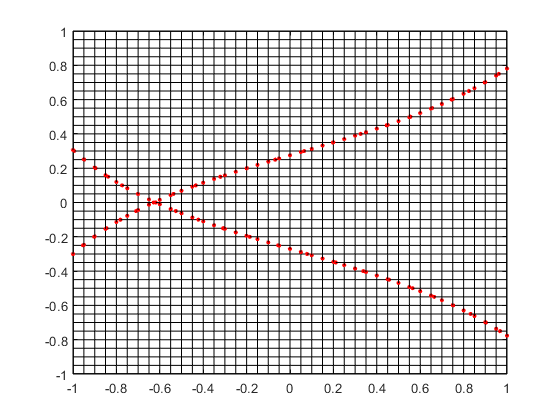

[INFO] Creating ray workspace ray node list.


% axis equal;
% title('WCC Ray-Workspace Plot'); 
% figure
 
    dofs_to_plot_2_DoF      = [1 2]; 
    % dofs_to_plot_2_DoF      = [4 5]; 
%     figure
    fixed_values = ws_sim.grid.q_begin' + ws_sim.grid.delta_q' .* [1 1 0 0 ];
    ws_sim.workspace.plotRayWorkspace(dofs_to_plot_2_DoF, fixed_values);

axis equal;
xlim([-pi/5 pi/5]);ylim([-pi/5 pi/5]);
% xlim([0 1]);ylim([0 1]);
x0=100;
y0=100;
width=300;
height=300;
set(gcf,'position',[x0,y0,width,height])

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom 0.98*ax_width 0.98*ax_height];

figure
fixed_values = ws_sim.grid.q_begin' + ws_sim.grid.delta_q' .* [1 1 7 0 0 7];
ws_sim.workspace.plotRayWorkspace(dofs_to_plot_2_DoF, fixed_values);
axis equal;
xlim([-pi/5 pi/5]);ylim([-pi/5 pi/5]);
% xlim([0 1]);ylim([0 1]);
x0=100;
y0=100;
width=300;
height=300;
set(gcf,'position',[x0,y0,width,height])
ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom 0.98*ax_width 0.98*ax_height];


figure
fixed_values = ws_sim.grid.q_begin' + ws_sim.grid.delta_q' .* [1 1 13 0 0 13];
ws_sim.workspace.plotRayWorkspace(dofs_to_plot_2_DoF, fixed_values);
axis equal;
xlim([-pi/5 pi/5]);ylim([-pi/5 pi/5]);
% xlim([0 1]);ylim([0 1]);
x0=100;
y0=100;
width=300;
height=300;
set(gcf,'position',[x0,y0,width,height])
ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom 0.98*ax_width 0.98*ax_height];


figure
fixed_values = ws_sim.grid.q_begin' + ws_sim.grid.delta_q' .* [1 1 19 0 0 19];
ws_sim.workspace.plotRayWorkspace(dofs_to_plot_2_DoF, fixed_values);
axis equal;
xlim([-pi/5 pi/5]);ylim([-pi/5 pi/5]);
% xlim([0 1]);ylim([0 1]);
x0=100;
y0=100;
width=300;
height=300;
set(gcf,'position',[x0,y0,width,height])
ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom 0.98*ax_width 0.98*ax_height];


figure
fixed_values = ws_sim.grid.q_begin' + ws_sim.grid.delta_q' .* [1 1 25 0 0 25];
ws_sim.workspace.plotRayWorkspace(dofs_to_plot_2_DoF, fixed_values);
axis equal;
xlim([-pi/5 pi/5]);ylim([-pi/5 pi/5]);
% xlim([0 1]);ylim([0 1]);
x0=100;
y0=100;
width=300;
height=300;
set(gcf,'position',[x0,y0,width,height])
ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom 0.98*ax_width 0.98*ax_height];
